## Offline Ensembles

Detection of offline synchronous neuronal ensembles, as described in

Chang, H., Esteves, I. M., Neumann, A. R., Mohajerani, M. H., McNaughton, B. L. (2022), Cortical Reactivation of Non-Spatial and Spatial Memory Representations Coordinate with Hippocampus to Form a Memory Dialogue. *bioRxiv*. [https://doi.org/10.1101/2022.12.16.520658](https://doi.org/10.1101/2022.12.16.520658)

clear
addpath(fullfile('helpers'))

### Load RUN data

Begin by loading the provided sample data.

load sample_data/params.mat
params

params = struct with fields:
        fs: 19.0349
        ts: [12000×1 double]
      topo: [1×1 struct]
    planes: [1×1 struct]


`params` contains relevant imaging parameters, including the sampling rate `fs` in Hz and the timestamps of individual frames `ts`.

load sample_data/RUN/behaviour.mat
load sample_data/RUN/deconv.mat
behaviour

behaviour = struct with fields:
       trials: [40×1 double]
     unit_pos: [12000×1 double]
     unit_vel: [12000×1 double]
    vr_length: 150


whos deconv

  Name            Size                Bytes  Class     Attributes

  deconv      12000x180            17280000  double              



`behaviour` contains the animal's linear position over the treadmill `unit_pos` in cm, velocity `unit_vel` in cm/s, indices to the start of each lap `trials` and the length of the environment `vr_length`.

`deconv` is a matrix of the time course vectors of deconvolved calcium traces, with rows as frames and columns as neurons.

### Process RUN data

We need to obtain the activity of each neuron as a function of position and lap number. This is achieved with the companion function `make_stacks`. The default options are `'bins', 50` for 50 spatial bins and `'sd', 4` for a Gaussian smoothing kernel of 4 cm standard deviations.

stack = make_stacks(behaviour, deconv);
stack

stack = struct with fields:
    behaviour: [1×1 struct]
       raster: {180×1 cell}
        stack: [50×180 double]


`raster` contains neurons' responses as a function of lap and position. Illustrated are the `raster` for the first 25 neurons:

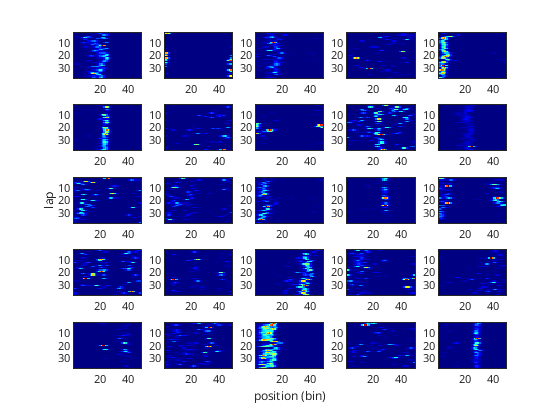

figure
for ii = 1:25
    subplot(5, 5, ii);
    imagesc(stack.raster{ii});
end
colormap jet
subplot(5, 5, 11);
ylabel('lap');
subplot(5, 5, 23);
xlabel('position (bin)');

`stack` contains the average response as a function of position, normalized between 0 and 1:

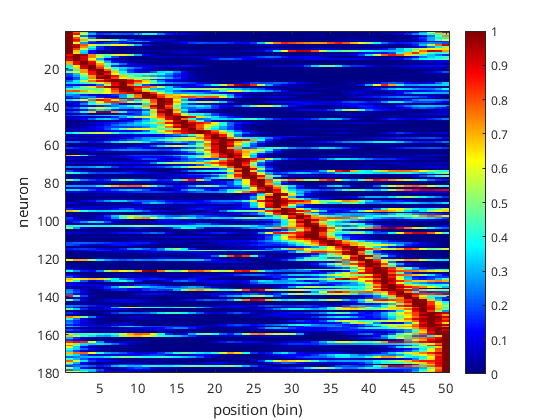

[~, order] = max(stack.stack);
[~, order] = sort(order);

figure
imagesc(stack.stack(:, order)')
colormap jet
colorbar
xlabel('position (bin)')
ylabel('neuron')

### Load REST data

The sample resting data is stored in the folder `REST` and has the same structure as the RUN data.

load sample_data/REST/behaviour.mat
load sample_data/REST/deconv.mat

### Detect ensembles in REST using hierarchical clustering

The class `ensemble` will be used to handle all relevant analyses over neuronal activities during awake quiescence. Begin by instantiating an object:

obj = ensemble(behaviour, deconv, params);
obj.ops

ans = struct with fields:
       sig: 0.2000
    e_size: 5
     thres: 0.7500


The default parameters for hierarchical clustering are `'sig', 0.2` for a 200 ms Gaussian smoothing kernel over the time courses, `'e_size', 5` for a minimum of 5 members per ensemble, `'thres', 0.75` for a threshold of 0.75 or lower in the average linkage distance for hierarchical clustering. These parameters can be changed using the command `obj.set('name', value)` or defined during the creation of the object.

First, removing the movement epochs:

obj.rm_mvt;

Then, perform hierarchical clustering:

obj.hclust;
obj.ensembles

ans = struct with fields:
        R: [180×180 double]
    clust: {7×1 cell}
    order: [1×180 double]
     tree: [179×3 double]


The results of this analysis are saved under `obj.ensembles`. `R` contains the correlation matrix used for hierarchical clustering. `clust `contains individual detected ensembles and their member neurons. `order` defines the optimal ordering of neurons for the hierarchical tree (obtained from the function `optimalleaforder`). We can use these to visualize the ensemble clusters:

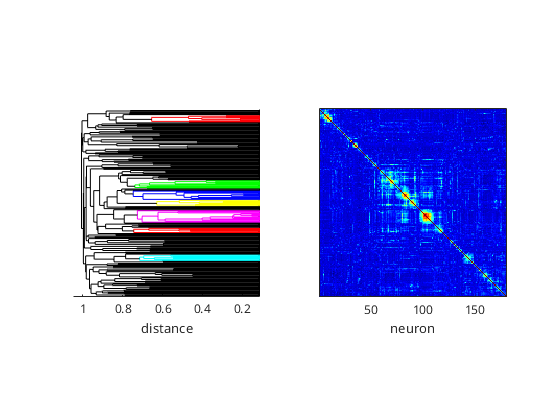

colours = hsv;
idx = linspace(1, size(colours, 1), length(obj.ensembles.clust));
colours = colours(round(idx), :);

figure
subplot(1, 2, 1)
h = dendrogram(obj.ensembles.tree, 0, 'reorder', obj.ensembles.order,...
   'orientation', 'left');
set(h, 'color', 'k');
for ii = 1:length(obj.ensembles.clust)
    idx = dendro_colours(obj.ensembles.tree, obj.ensembles.clust{ii});
    set(h(idx), 'color', colours(ii,:));
end
xlabel('distance')
yticklabels([])
axis square

subplot(1, 2, 2)
imagesc(obj.ensembles.R(obj.ensembles.order(end:-1:1), obj.ensembles.order(end:-1:1)))
axis square
colormap jet
yticklabels([])
xlabel('neuron')

### Visualizing ensemble features

We can visualize what the resting ensemble neurons were encoding during RUN with the `stack` structure obtained earlier.

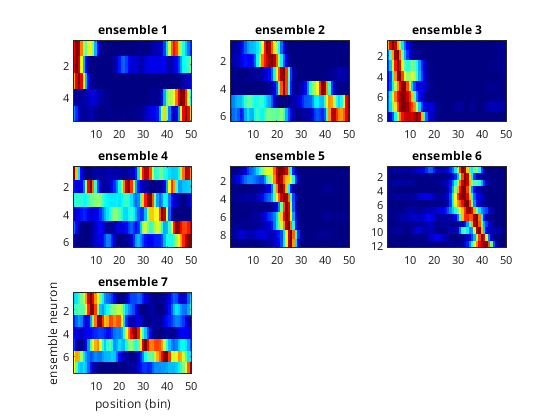

clust_stacks = cell(length(obj.ensembles.clust), 1);
for ii = 1:length(obj.ensembles.clust)
    clust_stacks{ii} = stack.stack(:, obj.ensembles.clust{ii});
    [~, order] = max(clust_stacks{ii});
    [~, order] = sort(order);
    clust_stacks{ii} = clust_stacks{ii}(:, order);
end

figure
k = ceil(sqrt(length(clust_stacks)));
for ii = 1:length(clust_stacks)
    subplot(k, k, ii)
    imagesc(clust_stacks{ii}')
    title(['ensemble ' num2str(ii)])
end
colormap jet
subplot(k, k, (ceil(length(clust_stacks) / k) - 1)*k + 1)
ylabel('ensemble neuron')
subplot(k, k, (ceil(length(clust_stacks) / k) - 1)*k + 1)
xlabel('position (bin)')

Ensemble #6 contains a short sequence of "place cells". Let us visualize the responses of individual ensemble members over laps.

(Notice that ensembles 3, 5 and 6 are the ones shown in Fig. 1d-f)

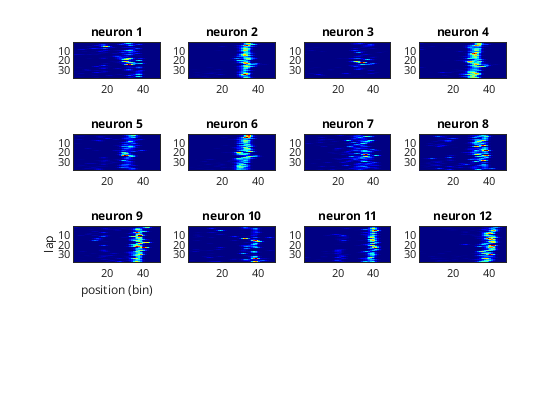

n = 6;

[~, order] = max(stack.stack(:, obj.ensembles.clust{n}));
[~, order] = sort(order);
clust_rasters = stack.raster(obj.ensembles.clust{n}(order));

figure
k = ceil(sqrt(length(clust_rasters)));
for ii = 1:length(clust_rasters)
    subplot(k, k, ii)
    imagesc(clust_rasters{ii})
    title(['neuron ' num2str(ii)])
end
colormap jet
subplot(k, k, (ceil(length(clust_rasters) / k) - 1)*k + 1)
ylabel('lap')
subplot(k, k, (ceil(length(clust_rasters) / k) - 1)*k + 1)
xlabel('position (bin)')

### Characterizing reactivation time courses by PCA-ICA

We obtain the time course vectors of reactivation strength for each ensemble using the *reconstruction ICA* method delineated in the paper.

obj.hPICA;
obj.hiepi

ans = struct with fields:
      pc: [180×7 double]
       W: [180×22 double]
    init: [180×7 double]
       X: [12000×180 double]
       z: [12000×7 double]


The results from this analysis are stored under `obj.hiepi`. `pc` stores the principal components estimated for each ensemble. `W` has whitening PCA eigenvectors appended to `pc`. `z` contains the reactivation time courses for each individual ensemble. See methods section for details on this analysis.

Let's plot the reactivation strength over time for ensembles 3, 5 and 6.

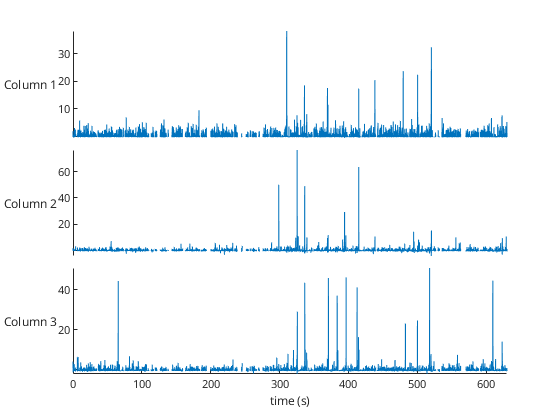

figure
t = linspace(0, size(obj.hiepi.z, 1) / obj.twop.fs, size(obj.hiepi.z, 1));
stackedplot(t, obj.hiepi.z(:, [3, 5, 6]))
xlabel('time (s)')

### Project RUN data into ensembles feature space

We can project the RUN deconv into the components space from PCA-ICA to obtain the features reactivated by individual ensembles.

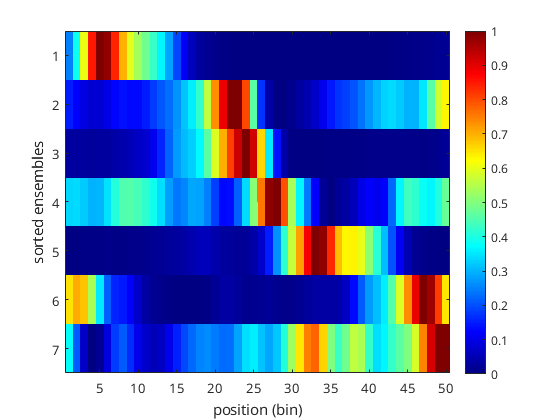

load sample_data/RUN/behaviour.mat
load sample_data/RUN/deconv.mat

deconv = (deconv - mean(deconv)) ./ std(deconv);
% null mean and unitary variance for projection
deconv = deconv * obj.hiepi.pc;
stack = make_stacks(behaviour, deconv);

[~, order] = max(stack.stack);
[~, order] = sort(order);

figure
imagesc(stack.stack(:, order)')
colormap jet
colorbar
xlabel('position (bin)')
ylabel('sorted ensembles')

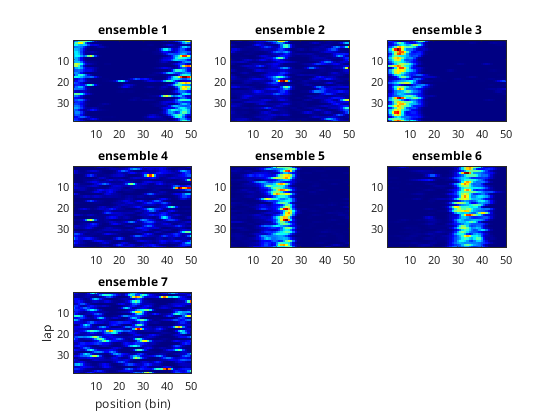

figure
for ii = 1:length(stack.raster)
    subplot(3, 3, ii);
    imagesc(stack.raster{ii});
    title(['ensemble ' num2str(ii)])
end
colormap jet
subplot(3, 3, 7);
ylabel('lap');
subplot(3, 3, 7);
xlabel('position (bin)');